filename = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Train";
imdsFasteners = imageDatastore(filename, "IncludeSubfolders",true, "LabelSource","foldernames");

[imdsTrain, imdsValidation] = splitEachLabel(imdsFasteners, 0.8, "randomized");

Using Deep Network Designer App

## Create dlnetwork 

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(19,"Name","fc")
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

net = initialize(net);

% We can see the size of our image is 337, 337, 3 but the input layers
% expects the image size to be 227,227,3 so we'll augment it
img = read(imdsTrain);
size(img)

ans =    337   337     3


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:00        0.001                             2.301
            1        1       00:00:01        0.001               0                  
           50        9       00:00:17        0.001            1.37            3.0176
          100       17       00:00:32        0.001               0            2.7118
          150       25       00:00:47        0.001         0.12455            3.2585
          180       30       00:00:56        0.001         0.12455            3.4348
Training stopped: Max epochs completed


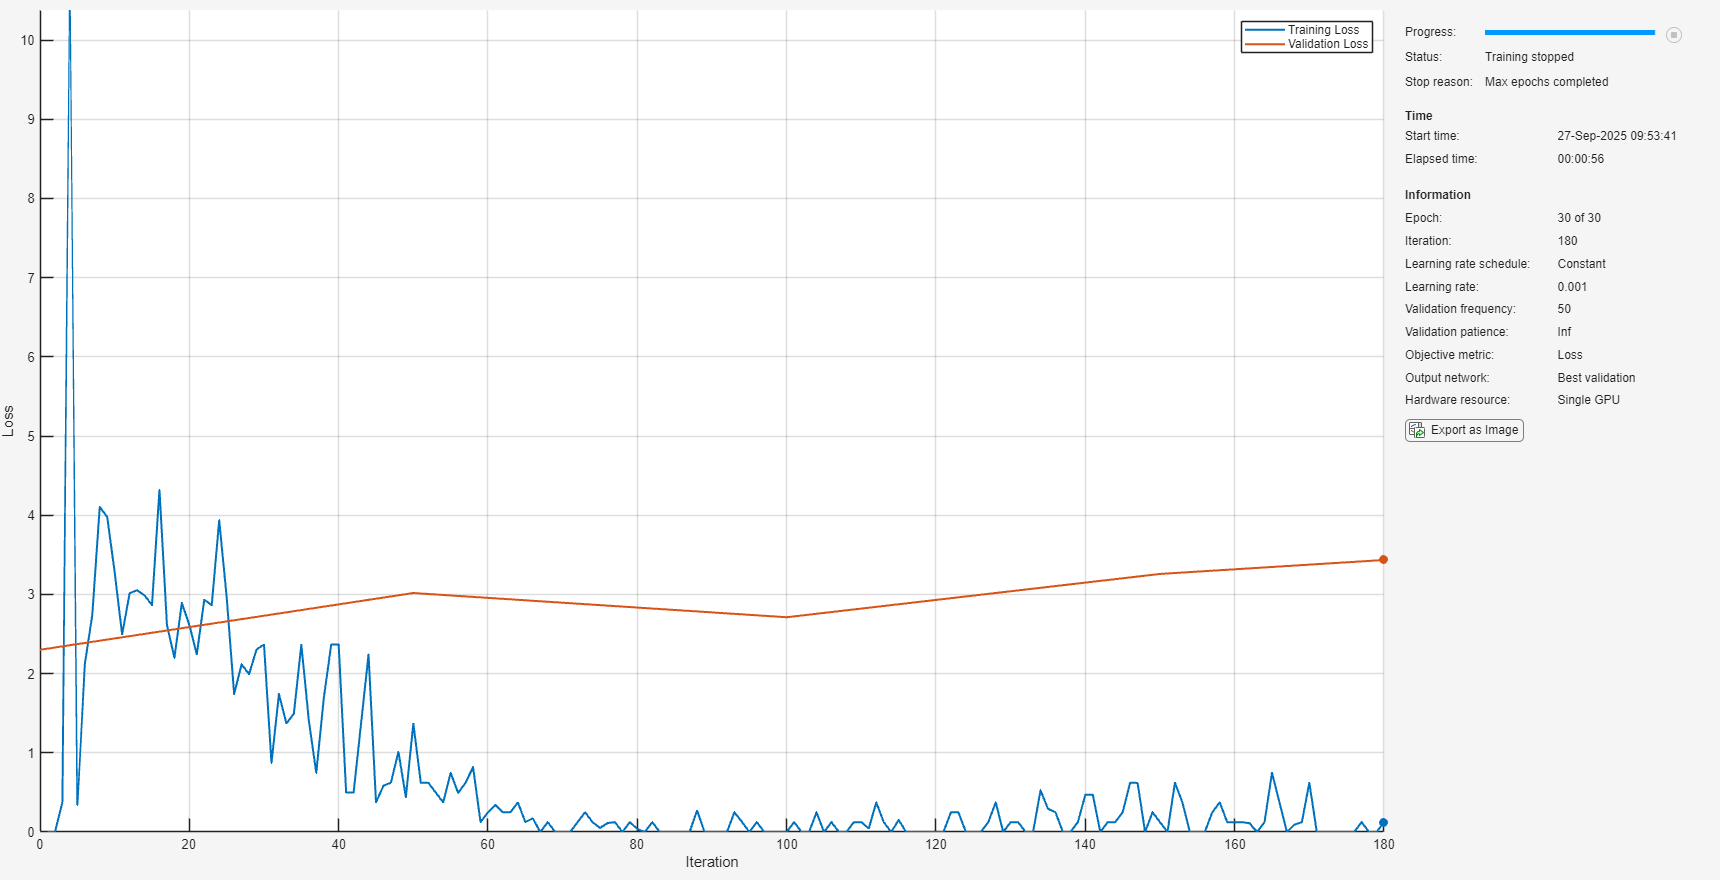

augTrain = augmentedImageDatastore([227 227], imdsTrain);
augVal = augmentedImageDatastore([227 227], imdsValidation);

% Now we have data, let's train
opts = trainingOptions("adam", "ValidationData",augVal, "Shuffle","every-epoch", "Plots","training-progress");
net = trainnet(augTrain, net, "crossentropy", opts);

net.Layers(2).Weights % we now have weights

ans = 3×3×3×32 single array
ans(:,:,1,1) =

   -0.0718    0.1265    0.0945
   -0.0338    0.0806    0.0782
   -0.0841    0.0070   -0.0655


ans(:,:,2,1) =

   -0.1087   -0.0826    0.0186
    0.0304   -0.0390   -0.0649
    0.1475    0.0818   -0.1001


ans(:,:,3,1) =

    0.1351   -0.0602    0.0204
   -0.0737    0.0240   -0.1139
   -0.0282   -0.0776    0.1244


ans(:,:,1,2) =

    0.1172   -0.1325    0.0450
    0.1139   -0.1018   -0.0543
   -0.0624   -0.0183    0.0612


ans(:,:,2,2) =

   -0.0856    0.0067    0.0817
   -0.0172   -0.1208    0.0460
    0.1105    0.0837    0.1168


ans(:,:,3,2) =

   -0.0696    0.0935    0.0446
   -0.1025    0.1151   -0.0061
   -0.1221   -0.0957   -0.0042


ans(:,:,1,3) =

    0.0949   -0.1406   -0.0026
   -0.0287    0.0748    0.0396
   -0.0298    0.0152    0.1136


ans(:,:,2,3) =

    0.1063    0.1114   -0.1318
    0.0176    0.1203   -0.1147
   -0.1127    0.0449    0.0980


ans(:,:,3,3) =

   -0.0570    0.0462   -0.1330
    0.1231   -0.1254    0.0895
   -0.

% Now lets predict new data
filename = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Test";
imdsTests = imageDatastore(filename, "IncludeSubfolders",true, "LabelSource","foldernames");

augTest = augmentedImageDatastore([227 227], imdsTests);

testPreds = minibatchpredict(net, augTest)

testPreds = 172×19 single matrix
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     

classes = categories(imdsTests.Labels);
testPredsClass = scores2label(testPreds, classes)

testPredsClass = 172×1 categorical array
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1in 
     Bolt5_16inx1in 
     Bolt5_16inx1in 
     Bolt5_16inx1in 
     Bolt5_16inx1-1_4in 
     Bolt5_16inx1in 
     Bolt5_16inx1in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     Bolt5_16inx3_4in 
     FinishNail1-1_4in 
     RoofingNail1-1_4in 
     RoofingNail1-1_4in 
     FinishNail1-1_4in 
     FinishNail1-1_4in 


testAccuracy = nnz(testPredsClass == imdsTests.Labels)/length(testPredsClass)

testAccuracy = 0.8488